# 基于MATLAB的目标分类——以动物分类为例

email：pietychen@sjtu.edu.cn

在本次大作业的实现中，我们使用了CNN来完成目标分类。

CNN（卷积神经网络）是一类包含卷积计算且具有深度结构的前馈神经网络。

## 卷积

以一个来自知乎的解释为例：“你在过去不同时刻惹女朋友生气的叠加，对女朋友现在坏心情的贡献就是卷积。”

在图像问题中，可以将卷积理解为一种提取图片特征的计算：

[A,map]=imread('./convolution.gif','frames','all');
mov=immovie(A,map);
implay(mov)

## 卷积神经网络

        神经网络是一种模拟人脑的神经网络以期能够实现类人工智能的机器学习技术。神经网络的基本单元是神经元，神经元模型是一个包含输入，输出与计算功能的模型。输入可以类比为神经元的树突，而输出可以类比为神经元的轴突，计算则可以类比为细胞核。连接是神经元中最重要的东西。每一个连接上都有一个权重。一个人工神经网络的训练算法就是让权重的值调整到最佳，以使得整个网络的预测效果最好。

        单个神经元能够获取到的图像特征是有限的，但如果使用数量足够多的卷积层，我们就能获取到足够高级足够丰富的图像特征。

        卷积神经网络就是卷积层与其他神经网络层的组合，用于获取丰富的图像特征帮助我们完成图像分类。

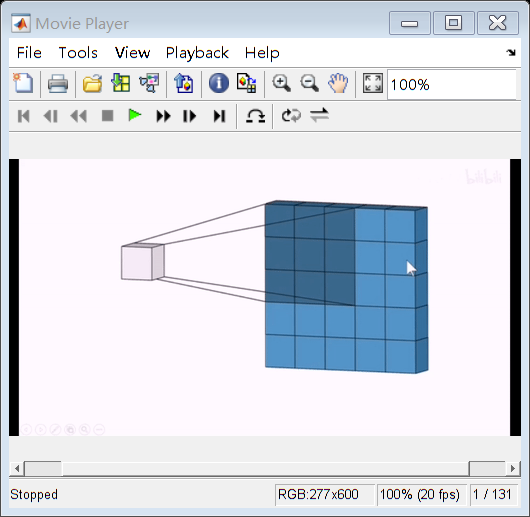

imshow(imread('./CNN.png'))

## 如何设计一个深度神经网络？

- 根据经验与需求自己搭建

- “站在巨人的肩膀上”——预训练模型与迁移学习

本次大作业我们使用了不带权重的AlexNet作为预训练模型，修改了其部分参数保证展示时的效率，故其准确率会有所下降。

deepNetworkDesigner是Deep Learning Toolbox工具箱中的一个应用，可以帮助我们显式的定义神经网络并生成相关代码。

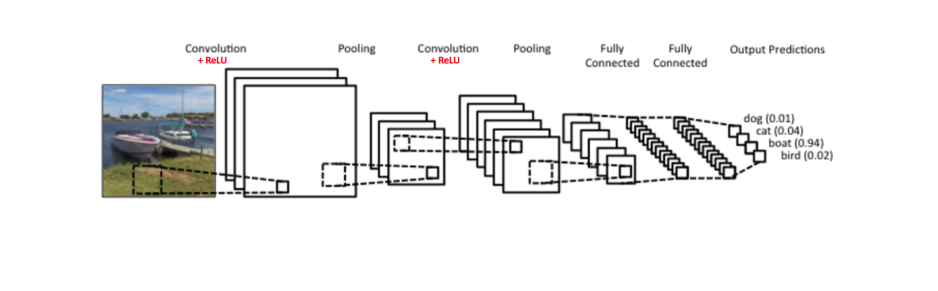

deepNetworkDesigner

clc
clear
close all

## 数据预处理

我们的数据来源为ImageNet与Kaggle，原始数据已经通过bat批处理文件全部转换为.jpg格式

数据预处理的目的是将所有图像resize到符合神经网络输入层的大小

file_path = './Dataset/';
format = '*.jpg';
classes = ["cat";"chicken";"cow";"dog";"sheep"];

idx = cell(size(classes,1),1);%创建一个保存每个类别图片数目的数组
total_sample_num = 0;

for i = 1:size(classes,1)
    class_dir = strcat(strcat(file_path,classes{i}),'\');
    %dir(strcat(class_dir,format));
    image_num = length(dir(strcat(class_dir,format)))
    idx{i} = image_num;
    total_sample_num = total_sample_num+image_num;
end

image_num = 1957

image_num = 1976

image_num = 1866

image_num = 2036

image_num = 1820

**数据集均衡分析**

分类神经网络一个很重要的要求是数据集均衡

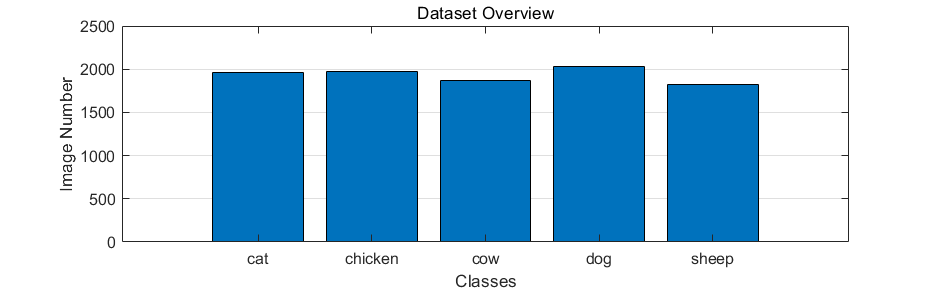

bar(cell2mat(idx))
xlabel('Classes')

xlim([-0.20 6.20])
ylim([0 2500])

set(gca,'XGrid','off','YGrid','on')
set(gca,'xticklabel',classes);

ylabel('Image Number')
title('Dataset Overview')

clf
total_sample_num

total_sample_num = 9655

## 图像预处理示例

sz_img = 128;%输入层size(128,128,3)
images = zeros(sz_img,sz_img,3);
labels = cell(total_sample_num,1);

**未进行处理的图像**

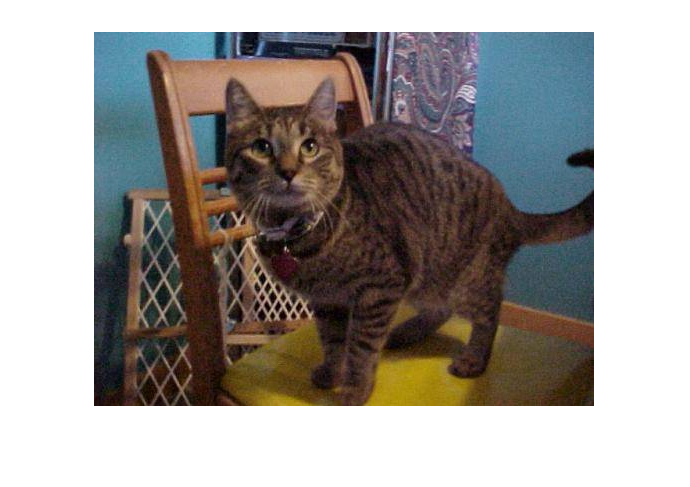

img = imread('./Dataset/cat/cats_00001.jpg');

imshow(img)

**处理之后的图像**

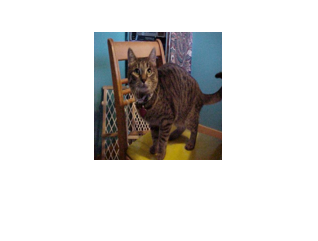

img = imresize(img,[sz_img,sz_img]);
images = img;
imshow(img)

clf

## 数据读取与存储

***数据读取与预处理花费时间较长，不做展示***

数据成功读取后将其保存在一个mat文件中，在使用时直接load会大大提高程序运行效率

k = 0;
for i = 1:size(classes,1)
    class_dir = strcat(strcat(file_path,classes{i}),'\');
    begin_idx = k+1
    end_idx = k+idx{i}
    for j = begin_idx:end_idx
        temp = dir(strcat(class_dir,format));
        image_name = temp(j-k).name;
        img = imresize(imread(strcat(class_dir,image_name)),[sz_img,sz_img]);
        images(:,:,:,j) = img;
        labels{j} = i-1;
    end
    k = k+idx{i};
end

begin_idx = 1

end_idx = 1957

begin_idx = 1958

end_idx = 3933

begin_idx = 3934

end_idx = 5799

begin_idx = 5800

end_idx = 7835

begin_idx = 7836

end_idx = 9655

save dataset.mat images labels

## 读取数据

load dataset.mat
whos

  Name                     Size                        Bytes  Class     Attributes

  A                      277x600x1x131              21772200  uint8               
  class_dir                1x48                           96  char                
  classes                  5x1                           366  string              
  file_path                1x42                           84  char                
  format                   1x5                            10  char                
  i                        1x1                             8  double              
  idx                      5x1                           560  cell                
  image_num                1x1                             8  double              
  images                 128x128x3x9655            474562560  uint8               
  img                    128x128x3                     49152  uint8               
  labels                9655x1                       1081360  cell                
  m

## 展示部分图像及标签

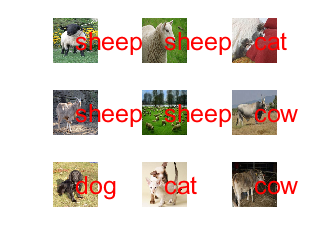

for i = 1:9%随机展示9 images和他们的labels
    idx = round(unifrnd(1,total_sample_num));
    subplot(3,3,i);
    imshow(images(:,:,:,idx))
    text(sz_img/2,sz_img/2,classes{double(labels{idx})+1},'color','r','fontsize',15)
end

clf

## 分割数据集

随机打乱整个数据集并将其分为训练集，验证集，测试集。

打乱数据集有利于提高训练准确度。

我们使用训练集进行神经网络的权重参数训练，用验证集进行训练结果验证，最后在测试集上计算准确度。

Y = categorical(labels); 

rand_idx = randperm(size(images,4));  
num_train = round(0.6*size(images,4)); 
num_val = round(0.3*size(images,4));  

X_train = double(images(:,:,:,rand_idx(1:num_train)))./255;
X_val = double(images(:,:,:,rand_idx(num_train+1:num_train+num_val)))./255;
X_test = double(images(:,:,:,rand_idx(num_train+num_val+1:end)))./255;  
    
Y_train = Y(rand_idx(1:num_train),:);
Y_val = Y(rand_idx(num_train+1:num_train+num_val),:);
Y_test = Y(rand_idx(num_train+num_val+1:end),:);

## 定义神经网络结构

输入层：输入规定大小的图片

卷积层：提取图像特征

激活层：将线性函数转换为非线性，从而可以逼近任何函数

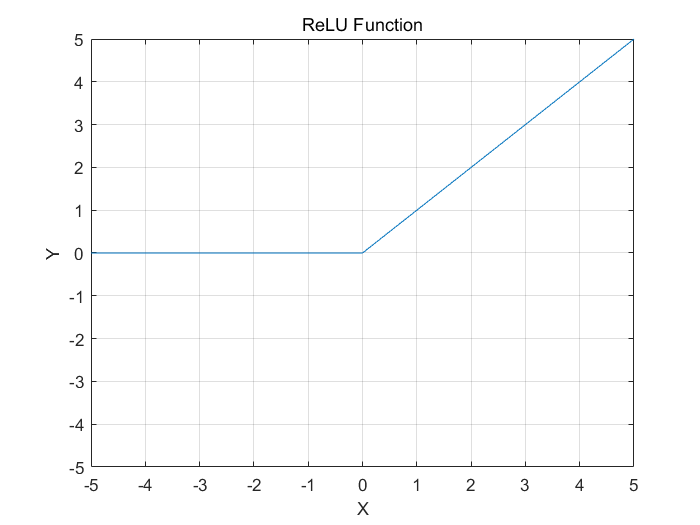

figure('NumberTitle', 'off', 'Name', 'ReLU function');

x=-5:0.1:5;
y=max(0,x);

plot(x,y);

xlabel('X');ylabel('Y');
grid on;
axis on;
axis([-5,5,-5,5]);

title('ReLU Function');

clf

池化层：丢弃一部分特征，防止过度拟合

全连接层：将神经网络产生的高维向量展开，用于结果输出

## 定义神经网络结构

layers = [
    imageInputLayer([128 128 3],"Name","imageinput")
    convolution2dLayer([11 11],96,"Name","conv1","BiasLearnRateFactor",2,"Stride",[4 4])
    reluLayer("Name","relu1")
    crossChannelNormalizationLayer(5,"Name","norm1","K",1)
    maxPooling2dLayer([3 3],"Name","pool1","Stride",[2 2])
    groupedConvolution2dLayer([5 5],128,2,"Name","conv2","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","relu2")
    crossChannelNormalizationLayer(5,"Name","norm2","K",1)
    maxPooling2dLayer([3 3],"Name","pool2","Stride",[2 2])
    convolution2dLayer([3 3],384,"Name","conv3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","relu3")
    groupedConvolution2dLayer([3 3],192,2,"Name","conv4","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","relu4")
    groupedConvolution2dLayer([3 3],128,2,"Name","conv5","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","relu5")
    maxPooling2dLayer([3 3],"Name","pool5","Stride",[2 2])
    fullyConnectedLayer(4096,"Name","fc6","BiasLearnRateFactor",2)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop6")
    fullyConnectedLayer(4096,"Name","fc7","BiasLearnRateFactor",2)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop7")
    fullyConnectedLayer(1000,"Name","fc8","BiasLearnRateFactor",2)
    fullyConnectedLayer(5,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## 可视化神经网络

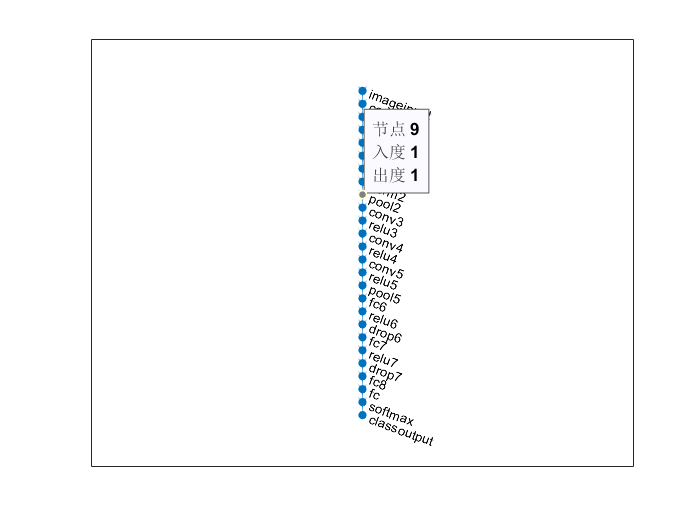

plot(layerGraph(layers));

analyzeNetwork(layers)
clf

## 指定训练超参数并训练网络

超参数的指定：也即我们平常所说的“炼丹”过程，需要通过经验与尝试来获得准确度较高的神经网络。

在单 GPU 上训练。
正在初始化输入数据归一化。


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量准确度　　｜　　验证准确度　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


｜　　　１　｜　　　　１　｜　　　　　００：００：１３　｜　　　３４．３８％　｜　　１９．７８％　｜　　１．６０５４　｜　１．６０９２　｜　　０．００７０　｜


｜　　　１　｜　　　５０　｜　　　　　００：００：５６　｜　　　１８．７５％　｜　　　　　　　　　｜　　１．６２８６　｜　　　　　　　　｜　　０．００７０　｜


｜　　　１　｜　　１００　｜　　　　　００：０１：５９　｜　　　１２．５０％　｜　　２０．５４％　｜　　１．６１８３　｜　１．６０２４　｜　　０．００７０　｜


｜　　　１　｜　　１５０　｜　　　　　００：０２：４７　｜　　　４３．７５％　｜　　　　　　　　　｜　　１．５１７３　｜　　　　　　　　｜　　０．００７０　｜


｜　　　２　｜　　２００　｜　　　　　００：０３：４５　｜　　　２５．００％　｜　　３７．０４％　｜　　１．７０９７　｜　１．４６１５　｜　　０．００７０　｜


｜　　　２　｜　　２５０　｜　　　　　００：０４：２４　｜　　　３１．２５％　｜　　　　　　　　　｜　　１．４９２５　｜　　　　　　　　｜　　０．００７０　｜


｜　　　２　｜　　３００　｜　　　　　００：０４：４０　｜　　　２８．１３％　｜　　３７．４２％　｜　　１．４８６１　｜　１．４１４６　｜　　０．００７０　｜


｜　　　２　｜　　３５０　｜　　　　　００：０４：５４　｜　　　５０．００％　｜　　　　　　　　　｜　　１．３２５９　｜　　　　　　　　｜　　０．００７０　｜


｜　　　３　｜　　４００　｜　　　　　００：０５：０９　｜　　　３７．５０％　｜　　４２．１５％　｜　　１．３６９１　｜　１．３３８２　｜　　０．００７０　｜


｜　　　３　｜　　４５０　｜　　　　　００：０５：２３　｜　　　４３．７５％　｜　　　　　　　　　｜　　１．２６３９　｜　　　　　　　　｜　　０．００７０　｜


｜　　　３　｜　　５００　｜　　　　　００：０５：３５　｜　　　５０．００％　｜　　４１．２５％　｜　　１．３５０３　｜　１．３２０４　｜　　０．００７０　｜


｜　　　４　｜　　５５０　｜　　　　　００：０５：４４　｜　　　３７．５０％　｜　　　　　　　　　｜　　１．２７８９　｜　　　　　　　　｜　　０．００７０　｜


｜　　　４　｜　　６００　｜　　　　　００：０５：５６　｜　　　５３．１３％　｜　　４５．１２％　｜　　１．０４４２　｜　１．２８９０　｜　　０．００７０　｜


｜　　　４　｜　　６５０　｜　　　　　００：０６：０７　｜　　　３７．５０％　｜　　　　　　　　　｜　　１．２３１２　｜　　　　　　　　｜　　０．００７０　｜


｜　　　４　｜　　７００　｜　　　　　００：０６：２２　｜　　　６２．５０％　｜　　５１．６４％　｜　　１．１１８８　｜　１．１６０７　｜　　０．００７０　｜


｜　　　５　｜　　７５０　｜　　　　　００：０６：３４　｜　　　５０．００％　｜　　　　　　　　　｜　　１．００９５　｜　　　　　　　　｜　　０．００７０　｜


｜　　　５　｜　　８００　｜　　　　　００：０６：４８　｜　　　５６．２５％　｜　　４８．１９％　｜　　１．０３０１　｜　１．２０７３　｜　　０．００７０　｜


｜　　　５　｜　　８５０　｜　　　　　００：０７：００　｜　　　４６．８８％　｜　　　　　　　　　｜　　１．２１２６　｜　　　　　　　　｜　　０．００７０　｜


｜　　　５　｜　　９００　｜　　　　　００：０７：１４　｜　　　５９．３８％　｜　　４８．２９％　｜　　１．０７２５　｜　１．１９２１　｜　　０．００７０　｜


｜　　　６　｜　　９５０　｜　　　　　００：０７：２５　｜　　　６５．６３％　｜　　　　　　　　　｜　　１．０７０２　｜　　　　　　　　｜　　０．００７０　｜


｜　　　６　｜　１０００　｜　　　　　００：０７：４０　｜　　　４６．８８％　｜　　６０．０６％　｜　　１．１６２２　｜　０．９９２３　｜　　０．００７０　｜


｜　　　６　｜　１０５０　｜　　　　　００：０７：５１　｜　　　５９．３８％　｜　　　　　　　　　｜　　０．９０７４　｜　　　　　　　　｜　　０．００７０　｜


｜　　　７　｜　１１００　｜　　　　　００：０８：０５　｜　　　６８．７５％　｜　　６０．７２％　｜　　０．７７１６　｜　０．９９２２　｜　　０．００７０　｜


｜　　　７　｜　１１５０　｜　　　　　００：０８：１６　｜　　　５６．２５％　｜　　　　　　　　　｜　　１．０１１０　｜　　　　　　　　｜　　０．００７０　｜


｜　　　７　｜　１２００　｜　　　　　００：０８：３０　｜　　　６２．５０％　｜　　６１．２４％　｜　　０．８９６９　｜　０．９６５４　｜　　０．００７０　｜


｜　　　７　｜　１２５０　｜　　　　　００：０８：４０　｜　　　６８．７５％　｜　　　　　　　　　｜　　０．９２５６　｜　　　　　　　　｜　　０．００７０　｜


｜　　　８　｜　１３００　｜　　　　　００：０８：５４　｜　　　６５．６３％　｜　　６２．５５％　｜　　１．０１７３　｜　０．９２１７　｜　　０．００７０　｜


｜　　　８　｜　１３５０　｜　　　　　００：０９：０５　｜　　　６５．６３％　｜　　　　　　　　　｜　　１．０１４０　｜　　　　　　　　｜　　０．００７０　｜


｜　　　８　｜　１４００　｜　　　　　００：０９：１９　｜　　　６８．７５％　｜　　６３．２７％　｜　　０．９０７４　｜　０．９４２８　｜　　０．００７０　｜


｜　　　９　｜　１４５０　｜　　　　　００：０９：３２　｜　　　６２．５０％　｜　　　　　　　　　｜　　０．８２１０　｜　　　　　　　　｜　　０．００７０　｜


｜　　　９　｜　１５００　｜　　　　　００：０９：４４　｜　　　８７．５０％　｜　　６３．００％　｜　　０．５３５８　｜　０．９５５４　｜　　０．００７０　｜


｜　　　９　｜　１５５０　｜　　　　　００：０９：４６　｜　　　７８．１３％　｜　　　　　　　　　｜　　０．６１０３　｜　　　　　　　　｜　　０．００７０　｜


｜　　　９　｜　１６００　｜　　　　　００：０９：５０　｜　　　６２．５０％　｜　　６３．４１％　｜　　０．８６１６　｜　０．９４６０　｜　　０．００７０　｜


｜　　１０　｜　１６５０　｜　　　　　００：０９：５２　｜　　　６５．６３％　｜　　　　　　　　　｜　　０．９１４６　｜　　　　　　　　｜　　０．００７０　｜


｜　　１０　｜　１７００　｜　　　　　００：０９：５６　｜　　　７５．００％　｜　　６３．００％　｜　　０．７２９２　｜　０．９８６４　｜　　０．００７０　｜


｜　　１０　｜　１７５０　｜　　　　　００：０９：５８　｜　　　５０．００％　｜　　　　　　　　　｜　　１．１８５１　｜　　　　　　　　｜　　０．００７０　｜


｜　　１０　｜　１８００　｜　　　　　００：１０：０２　｜　　　６２．５０％　｜　　６４．１０％　｜　　０．９４１０　｜　０．９０２５　｜　　０．００７０　｜


｜　　１１　｜　１８５０　｜　　　　　００：１０：０４　｜　　　７８．１３％　｜　　　　　　　　　｜　　０．６５９２　｜　　　　　　　　｜　　０．００７０　｜


｜　　１１　｜　１９００　｜　　　　　００：１０：０８　｜　　　７５．００％　｜　　６５．３８％　｜　　０．７６３１　｜　０．９２１２　｜　　０．００７０　｜


｜　　１１　｜　１９５０　｜　　　　　００：１０：１０　｜　　　６８．７５％　｜　　　　　　　　　｜　　０．７５９２　｜　　　　　　　　｜　　０．００７０　｜


｜　　１２　｜　２０００　｜　　　　　００：１０：１４　｜　　　８４．３８％　｜　　６６．１４％　｜　　０．４０６１　｜　０．８８９８　｜　　０．００７０　｜


｜　　１２　｜　２０５０　｜　　　　　００：１０：１６　｜　　　７８．１３％　｜　　　　　　　　　｜　　０．４５８１　｜　　　　　　　　｜　　０．００７０　｜


｜　　１２　｜　２１００　｜　　　　　００：１０：２０　｜　　　８１．２５％　｜　　６５．３８％　｜　　０．５９００　｜　１．０２８４　｜　　０．００７０　｜


｜　　１２　｜　２１５０　｜　　　　　００：１０：２２　｜　　　８１．２５％　｜　　　　　　　　　｜　　０．４９２１　｜　　　　　　　　｜　　０．００７０　｜


｜　　１２　｜　２１７２　｜　　　　　００：１０：２５　｜　　　４６．８８％　｜　　６４．６２％　｜　　０．９７８８　｜　０．９７２９　｜　　０．００７０　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


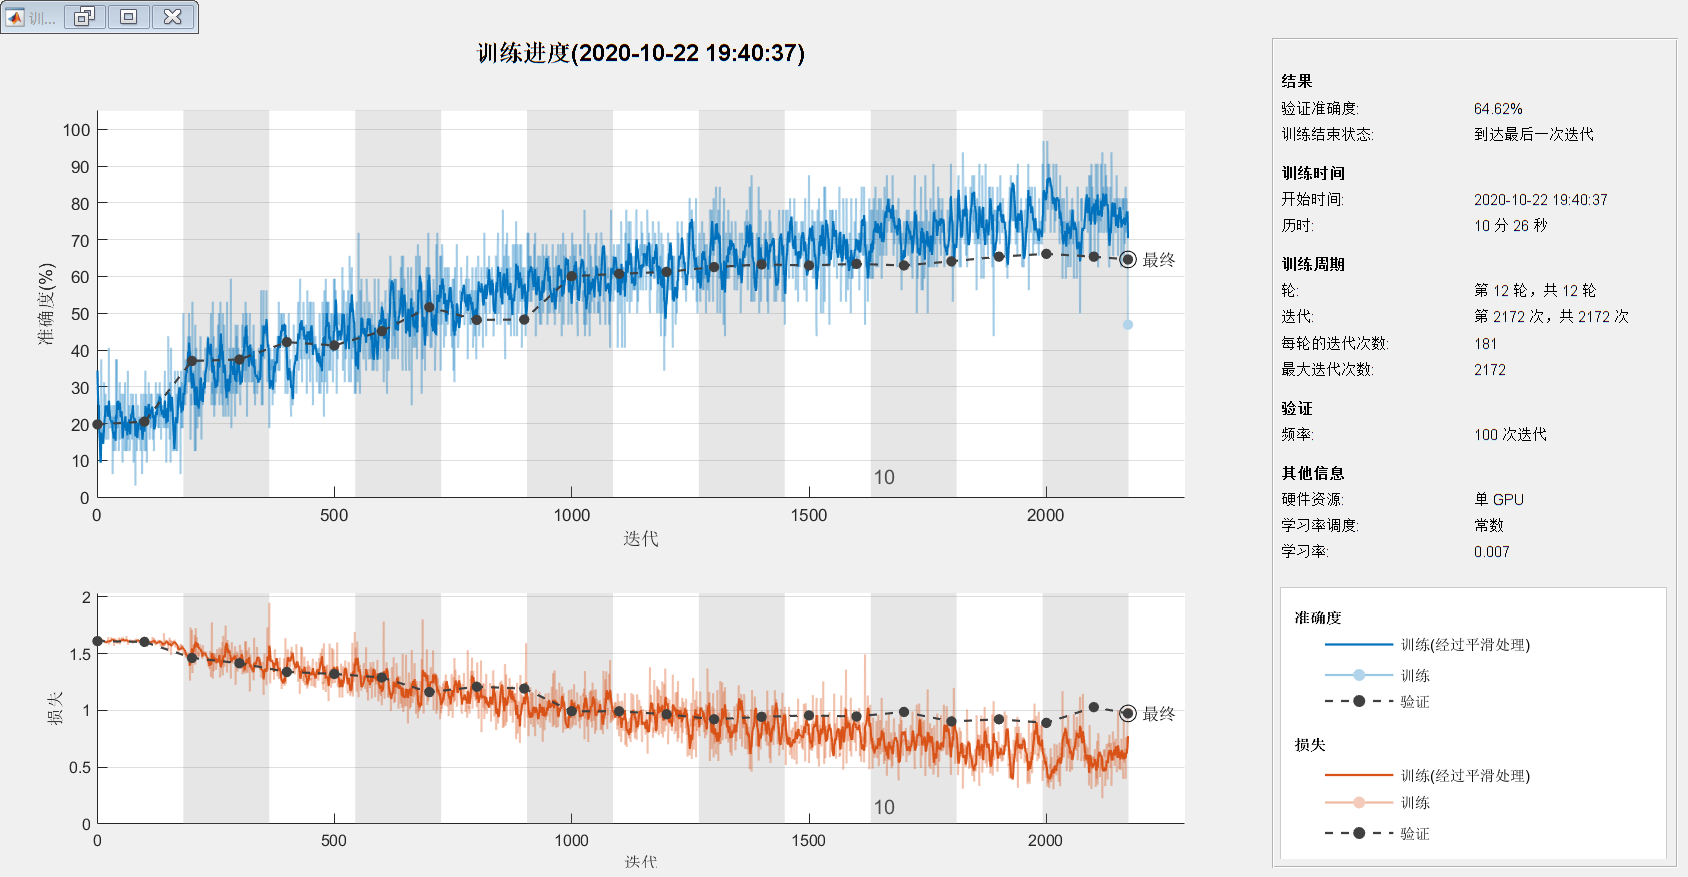

options = trainingOptions('sgdm',...                              
                          'MiniBatchSize',32, ...
                          'MaxEpochs',12,...                 
                          'ValidationData',{X_val,Y_val},... 
                          'Verbose',true, ...                
                          'Shuffle','every-epoch', ...
                          'ValidationFrequency',100, ...
                          'InitialLearnRate',0.007,...
                          'Plots','training-progress');
net_cnn = trainNetwork(X_train,Y_train,layers,options);

## 卷积层特征

以第一层卷积为例，它提取了图像的底层特征，如图像的轮廓

随着卷积神经网络的深入，低层特征（如图像轮廓）会逐渐丢失，高层特征（如图像纹理）则会逐渐凸显

layer = 2;
name = net_cnn.Layers(layer).Name
channels = 1:16;

name = 'conv1'

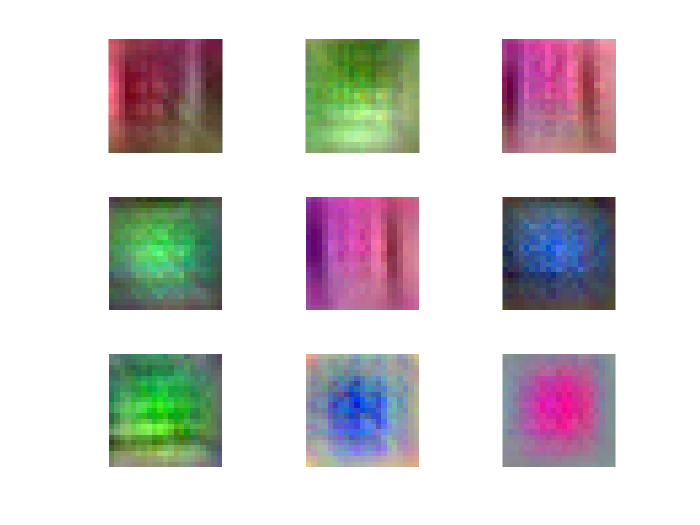

I = deepDreamImage(net_cnn,layer,channels, ...
    'PyramidLevels',3, ...
    'Verbose',0);
figure
for i = 1:9
    subplot(3,3,i)
    imshow(I(:,:,:,i))
end
clf

## 验证集准确度

多次改变超参数进行训练得到的验证集准确度如下：

val_acc = [
    61.58 65.25 68.00 66.39 65.82 65.72 64.98 64.37 64.19 64.01 63.96;
    61.79 65.38 68.12 66.47 66.00 65.79 65.32 64.97 64.44 64.17 64.01;
    62.01 65.49 68.33 66.56 66.14 65.90 65.56 65.12 64.88 64.39 64.17;
    62.03 65.51 68.36 66.61 66.17 65.91 65.59 65.00 64.91 64.44 64.1;
    ]; 

验证集准确度图像

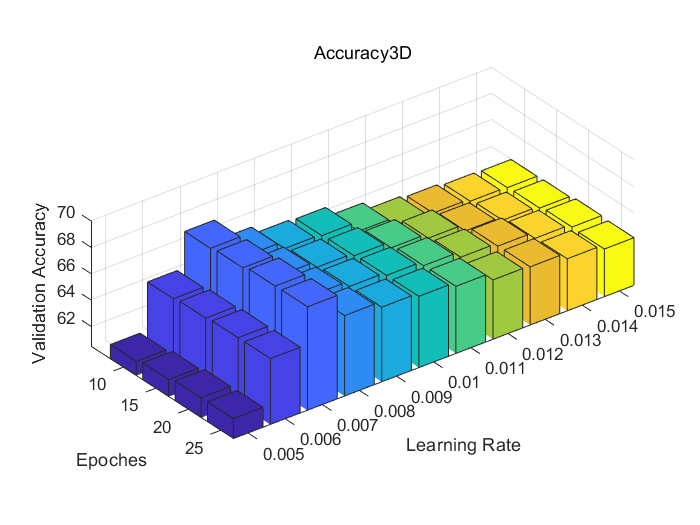

bar3(val_acc);

set(gca,'xticklabel',0.005:0.001:0.015);
set(gca,'yticklabel',10:5:25);

zlim([60.5,70]);
xlabel('Learning Rate');
ylabel('Epoches');
zlabel('Validation Accuracy');

title('Accuracy3D');

colorbar off
clf

经验证，学习率0.007，迭代次数20次时可以获得当前网络下较好的训练结果

## 测试集准确度

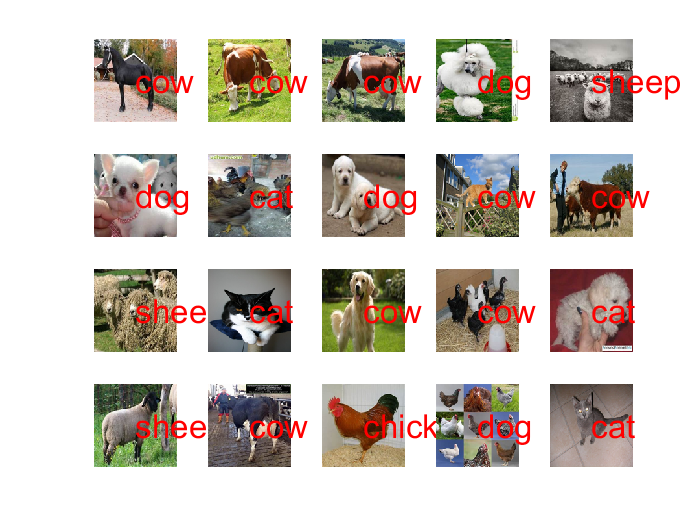

testLabel = classify(net_cnn,X_test);
for i = 1:20
    subplot(4,5,i);
    imshow(X_test(:,:,:,i))
    double(testLabel(i));
    text(sz_img/2,sz_img/2,classes{double(testLabel(i))},'color','r','fontsize',20)
end

clf
precision = sum(testLabel==Y_test)/numel(testLabel);
disp(['Test Accuracy：',num2str(precision*100),'%'])

Test Accuracy：66.6321%


## 总结

- MATLAB实时编辑器与Deep Learning Toolbox可谓相辅相成，两者搭配使用能够显式的定义与训练神经网络，相较Pytorch/Tensorflow等主流的深度学习框架更容易上手；

- 训练准确率欠佳的原因主要是预训练模型自带的卷积层并不十分适用于本次数据集图片的输入大小，想要获得较高准确率还是需要足够的网络搭建经验与训练尝试。